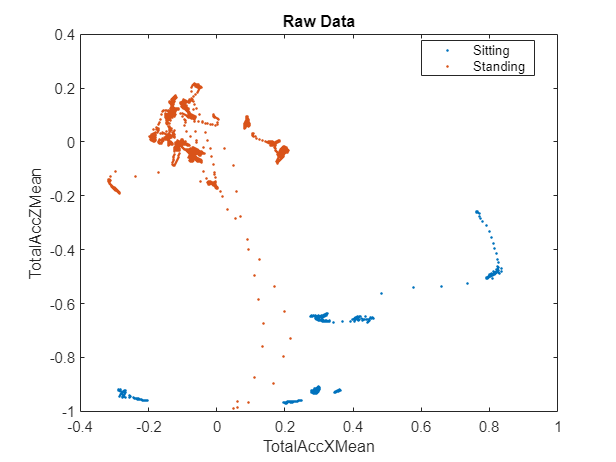

load humanactivity.mat

%sorting only the sitting (Iid=1) and standing (id=2)
feat_id = sortrows(cat(2,feat,actid),61); %concatenate and sort the feature matrix
                                          % with its ID as the last column 

x       = feat_id(1:12070,1); %change the column to 
y       = feat_id(1:12070,3); %choose the features (TotalAccXMean and TotalAccZMean)
labels  = feat_id(1:12070,61);

%plot
gscatter(x,y,labels);
xlabel('TotalAccXMean')
ylabel('TotalAccZMean')
legend('Sitting', 'Standing')
title('Raw Data')

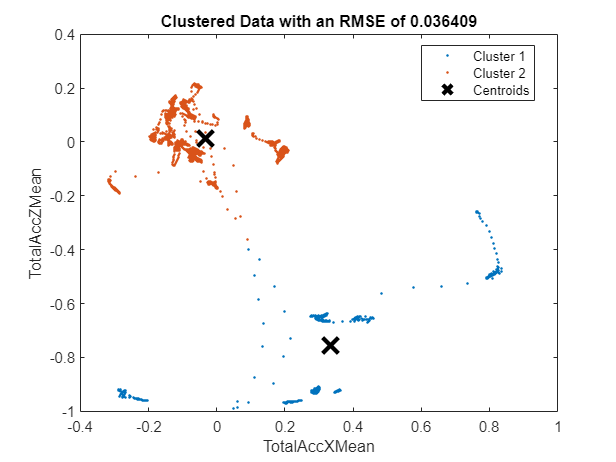

[idx, C] = kmeans([x,y], 2); %clustering based on two variables into two clusters

rmse = sqrt(mean((labels - idx).^2));

%plot results
gscatter(x,y,idx)
hold on
plot(C(:,1),C(:,2),'kx','MarkerSize',15,'LineWidth',3)
hold off
xlabel('TotalAccXMean')
ylabel('TotalAccZMean')
legend('Cluster 1', 'Cluster 2', 'Centroids')
title("Clustered Data with an RMSE of " + rmse);